# `State Diagram Transitioning `

# `&`

# `Automatic Emergency Braking`

`Matlab & Simulink`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Autonomy in Vehicles ECE 5553  | Ohio State University | 2/20/2023`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents`

`1. Introduction `

`2. `

`3. Conclusions and future work`

`4. Functions`

# `Background `

`The Simulink model identifies obstacles and implements the Stateflow chart, which has access to an emergency braking system only in this demonstration. Further decision making can be added to include smooth velocity transitions during state changes and add additional meta states for a more robust state transition diagram.`

# `Model Specifics 		`

`longitudinal velocity controller (PID)`

`Automatic Adaptive Cruise Control?`

`Automatic Emergency Braking `

# `Simulation Specifics	`		

`    The host vehicle starts from zero position and velocity. The longitudinal controller tracks the set_point velocity (ego_velocity_set_point). There is a lead car (block) which starts 300 m ahead of the host vehicle with an initial velocity of 5 m/s. A sine wave acceleration input is given for the lead vehicle. A simple detection methodology is used, which takes the relative distance between the ego vehicle and the closest vehicle/obstacle within 190 m range (sensor range). There is also a static obstacle that is introduced after a particular time to simulate an emergency condition. `

# Top Level Simulink Model

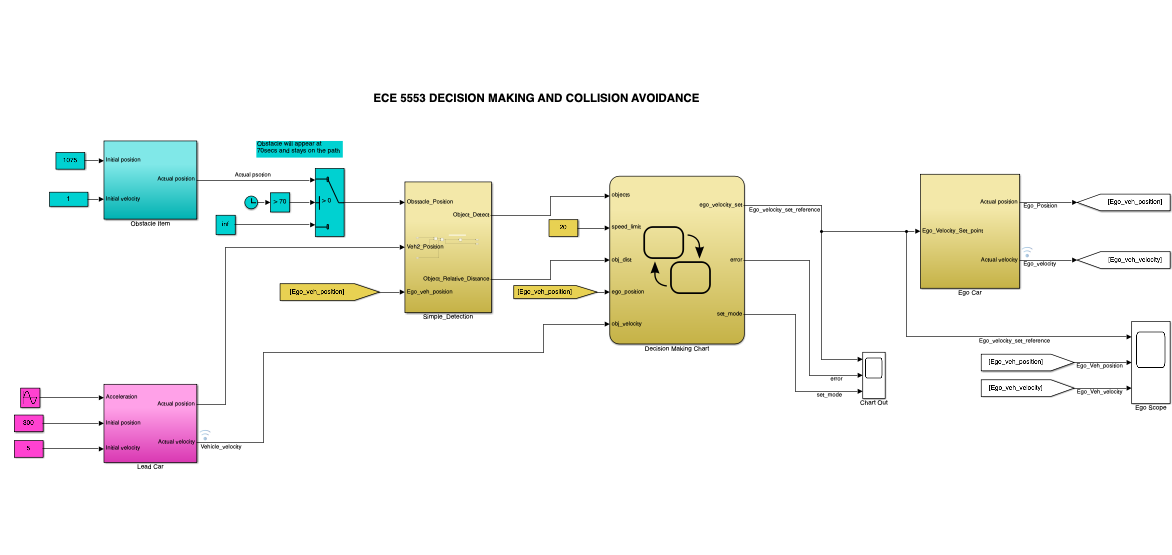

# State Flow Diagram - Decision Making Chart

Complete the state-flow chart in the Simulink model for the decision making. The logic is given in the flowchart below 

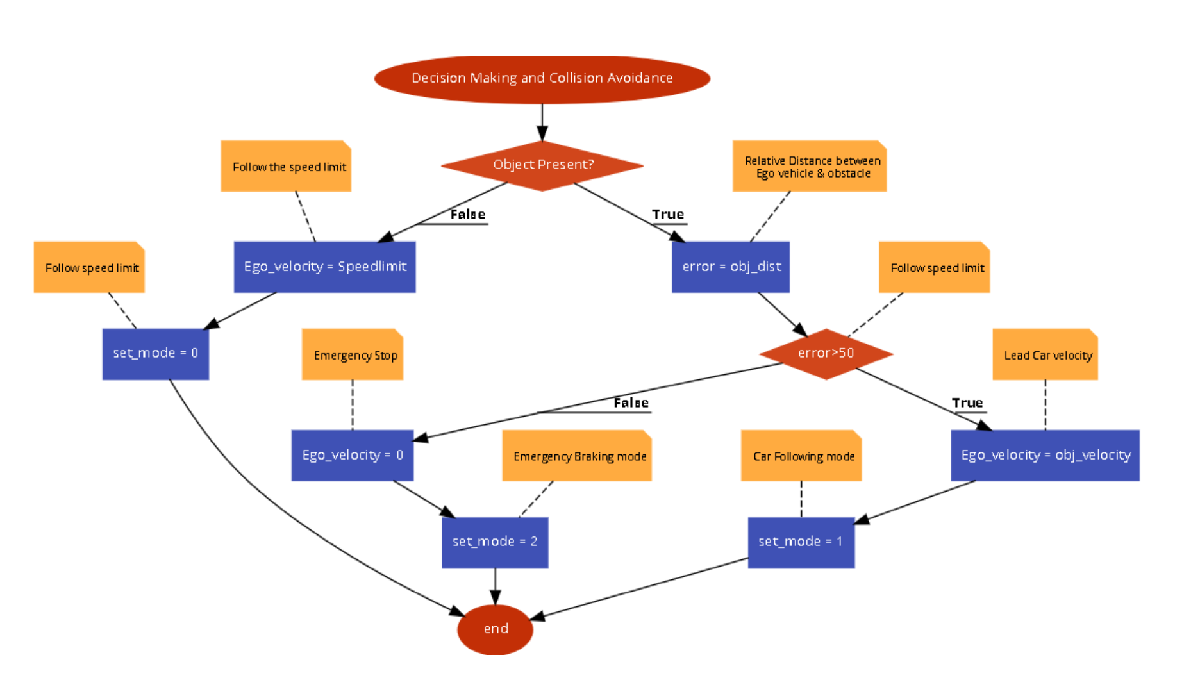

# Simulation and output

clc; clear; close all;
sim('AEBS_decision.slx');

ego_velocity_set =
    20

ego_velocity_set =
    20

ego_velocity_set =
    20

ego_velocity_set =
    20

ego_velocity_set =
    20



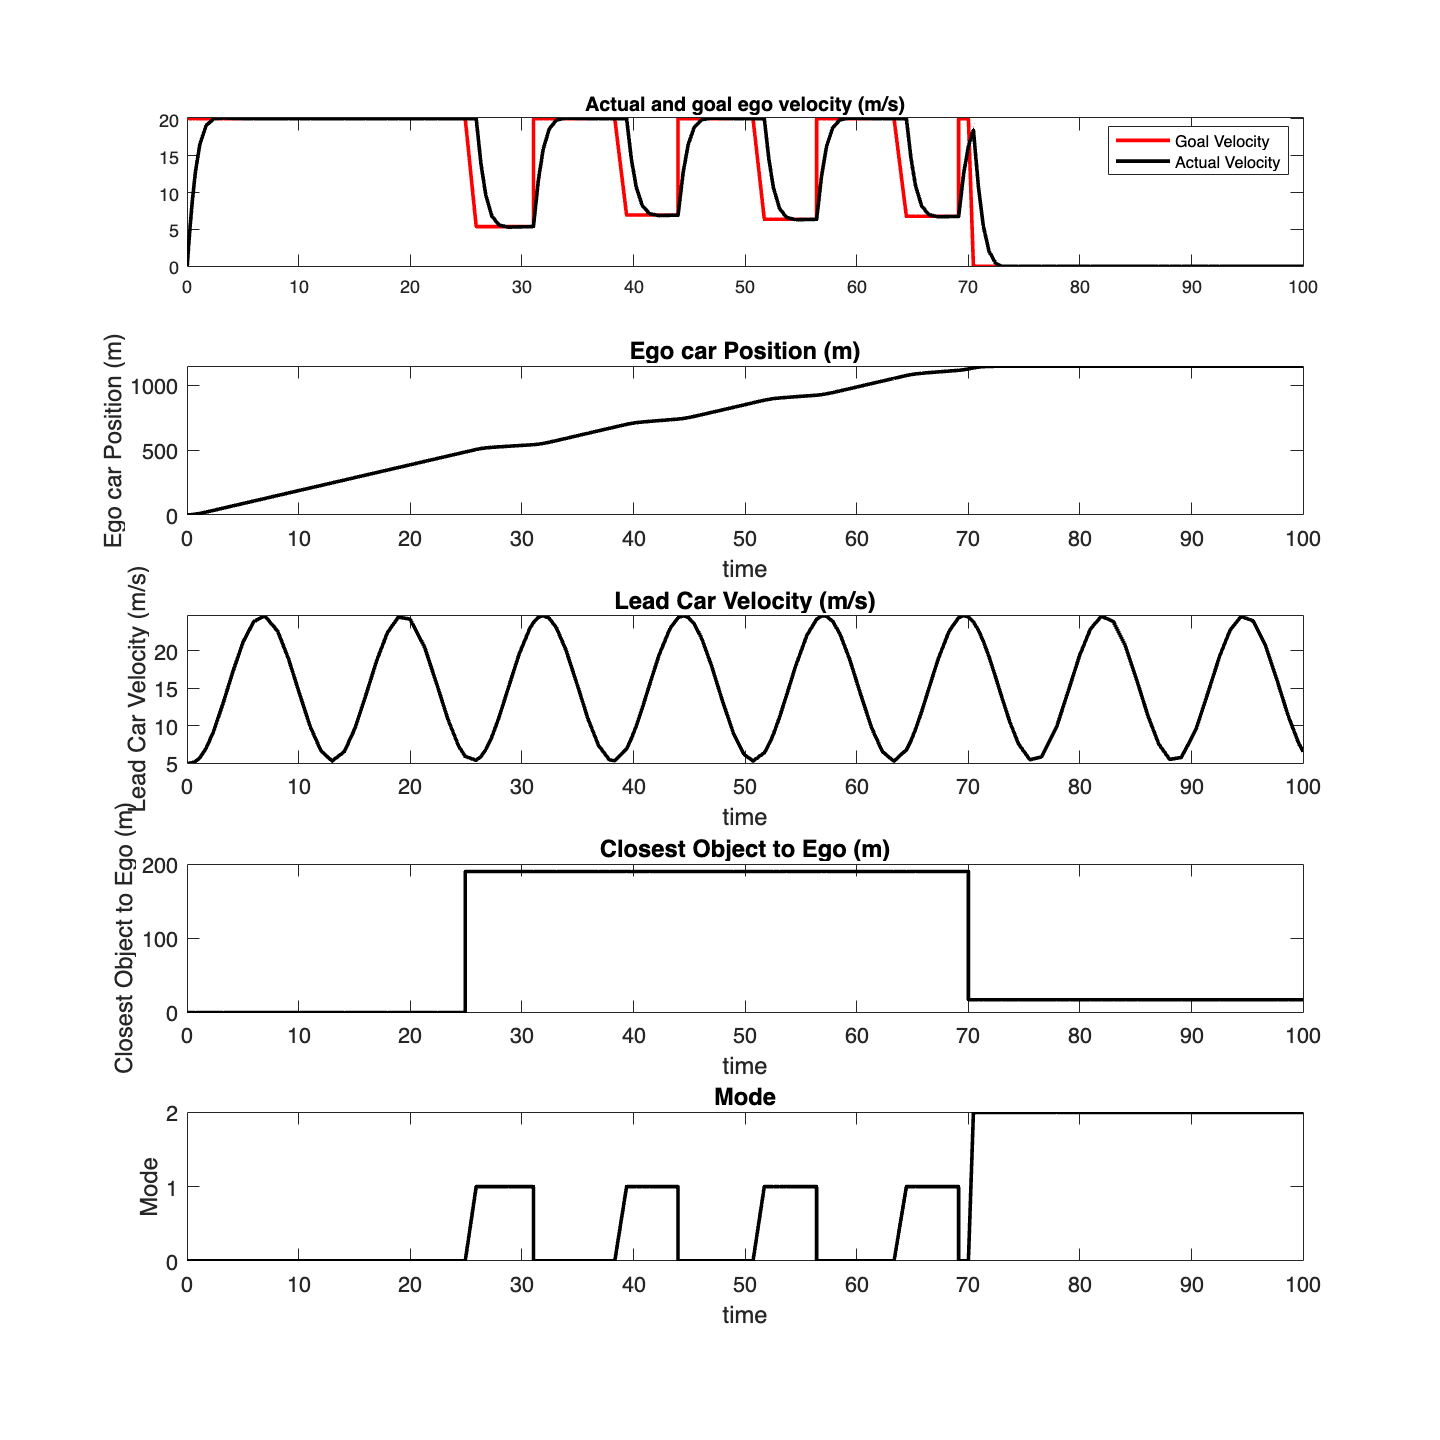

sim1 = Yout; 

ynames=["Actual and goal ego velocity (m/s)","","Ego car Position (m)","Lead Car Velocity (m/s)","Closest Object to Ego (m)","Mode"];

% Plotting 
figure()
n = length(ynames);
subplot(n-1,1,1), plot(time,sim1(:,1),'Linewidth',2,'Color',[1 0 0]), hold on, plot(time,sim1(:,2),'Linewidth',2,'Color',[0 0 0]), legend('Goal Velocity','Actual Velocity'), title(ynames(1))
for i = 3:1:n

    subplot(n-1,1,i-1) 
    plot(time,sim1(:,i),'Linewidth',2,'Color',[0 0 0])
    hold on;

    % plot labels 
    xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',12)

end 
set(gcf, 'Position', [0 0 1500 1500])

The mode 0 corresponds to speed limit following, the mode 1 corresponds to vehicle following, and the mode 2 corresponds to emergency braking.